# **UNIVERSIDADE FEDERAL DO CEARA**

## PROGRAMA DE POS-GRADUACAO EM ENGENHARIA ELETRICA

## CONTROLE ADAPTATIVO PREDITIVO

Vinicius Alexandre de Mesquita

clear all;
close all;
clc;

Limite de predição e de controle

N = 3;
Nu = 1;

Dados do sistema:

Ts = 1;
A = [1 -0.8];
B = [0.4 0.6];
Processo = filt([0 B],A,Ts)


Processo =
 
  0.4 z^-1 + 0.6 z^-2
  -------------------
     1 - 0.8 z^-1
 
Sample time: 1 seconds
Discrete-time transfer function.



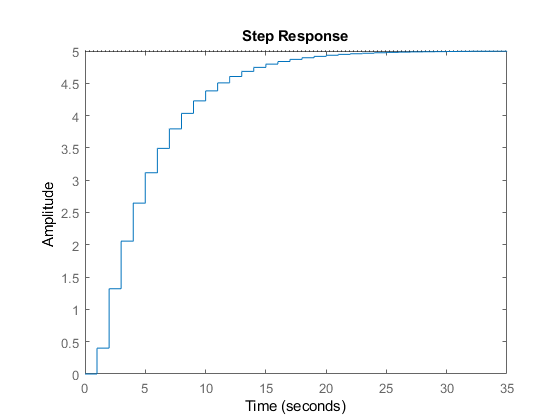

step(Processo)


na = length(A);
nb = length(B);

Saída do modelo sem perturbações: $x\left(t\right)=\frac{B\left(q^{-1} \right)}{A\left(q^{-1} \right)}$

x = filt([0 B],A,Ts);

Perturbações do sistema: $n\left(t\right)=\frac{C\left(q^{-1} \right)}{D\left(q^{-1} \right)}e\left(t\right)$

C = [1 0];
D = [1 -1];

Parâmetros de ponderação de controle e predição

lambda    = 0.0;
Ql        = lambda*eye(Nu);
W = ones(N,1);
MU0 = [1;zeros(Nu-1,1)];

Resposta ao impulso para determinar os coeficientes da matriz G

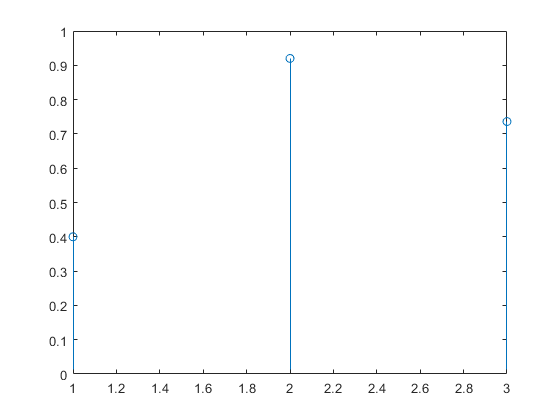

u=[1 zeros(1,N-1)];
yi=0;
s=0;
for i=1:N
    [h(i),yi] = filter(B,A,u(i),yi);
    s(i+1) = s(i)+h(i);
end
s=s(2:end);
stem(h)


G = zeros(N,N);
for i = 1:N
    G(i:end,i) = h(1:end-i+1);
end
G

G =     0.4000         0         0
    0.9200    0.4000         0
    0.7360    0.9200    0.4000


Gnu = G(:,1:Nu);
Gnu(Nu:end,end) = s(1:N-Nu+1)

Gnu =     0.4000
    1.3200
    2.0560


Cálculo de parâmetros

Ax      = -A(2:end);
Mt      = tril(ones(Nu));
M       = inv(Mt);

Cálculo dos ganhos

K1      = pinv(Gnu'*Gnu + M'*Ql*M)*Gnu';
K1      = K1(1,:)

K1 =     0.0653    0.2154    0.3354


K2      = pinv(Gnu'*Gnu + M'*Ql*M)*M'*Ql;
K2      = K2(1,:)

K2 = 0

Parâmetros de entrada para  S-function

Parametros.N        = N;
Parametros.Nu       = Nu;
Parametros.Qlambda  = Ql;
Parametros.Ts       = Ts;
Parametros.A        = A;
Parametros.B        = B;
Parametros.G        = G;
Parametros.Gnu      = Gnu;
Parametros.K1       = K1;
Parametros.K2       = K2;
Parametros.Ax       = Ax;
Parametros.M        = M;
Parametros.ub       = rand(N,1);


**Comparação com a função anterior**

Ce = [1 0];
[AA,BB,DD,Gant,F,E,H] = CalculaG(N,Processo,Ce);
Gant = Gant(:,1:Nu);
K = ((Gant'*Gant)+Ql)\Gant';
K = K(1,:)

K =     0.0653    0.2154    0.3354


KR = K*W

KR = 0.6160

KE = K*E

KE = 1.6331

KF = K*F

KF =     1.6331    1.2713    0.8191


**Gráficos**

Atualiza simulink

sim('Exercicio_9_Vinicius_Alexandre_sl',40)

Found algebraic loop containing: 
Exercicio_9_Vinicius_Alexandre_sl/Sum1
Exercicio_9_Vinicius_Alexandre_sl/Subsystem/S-Function
Exercicio_9_Vinicius_Alexandre_sl/Subsystem/S-Function
Exercicio_9_Vinicius_Alexandre_sl/Subsystem/Variable Selector2
Exercicio_9_Vinicius_Alexandre_sl/Subsystem1/Discrete FIR Filter1
Exercicio_

Aquisição de dados

[yer,u] = simul.signals.values;
tempo = simul.time;
y1 = yer(:,1);
y2 = yer(:,2);
ref = yer(:,3);
u1 = u(:,1);
u2 = u(:,2);

Geracao de graficos

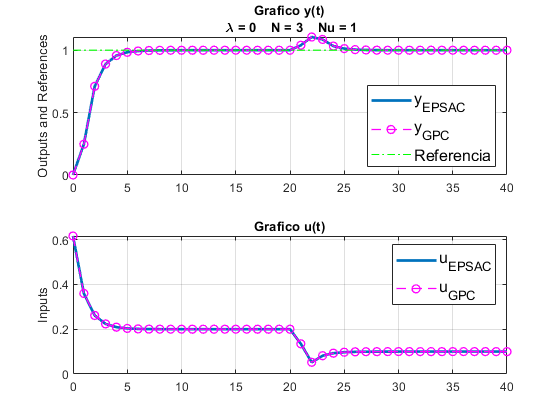

figure

subplot(2,1,1)
plot(tempo,y1,'-','LineWidth',2)
hold on
plot(tempo,y2,'m--o','LineWidth',1.0)
plot(tempo,ref,'g-.','LineWidth',0.8)
grid on;
ylabel('Outputs and References')
legend({'y_{EPSAC}','y_{GPC}','Referencia'},...
    'FontSize',12,'Location','southeast')
hold off
title ({['Grafico y(t)'],...
    [' \lambda = ' num2str(lambda) ...
     '    N = ' num2str(N) ...
     '    Nu = ' num2str(Nu)]})


subplot(2,1,2)
plot(tempo,u1,'-','LineWidth',2)
hold on
plot(tempo,u2,'m--o','LineWidth',1.0)
grid on;
ylabel('Inputs')
legend({'u_{EPSAC}','u_{GPC}'},...
        'FontSize',12)
title(['Grafico u(t)']);